# Lab 3: OFDM, Frame Synchronization & Equalization

## [Part 1]

clear; clc;

## (1) Frequency Spectrum for the OFDM symbol

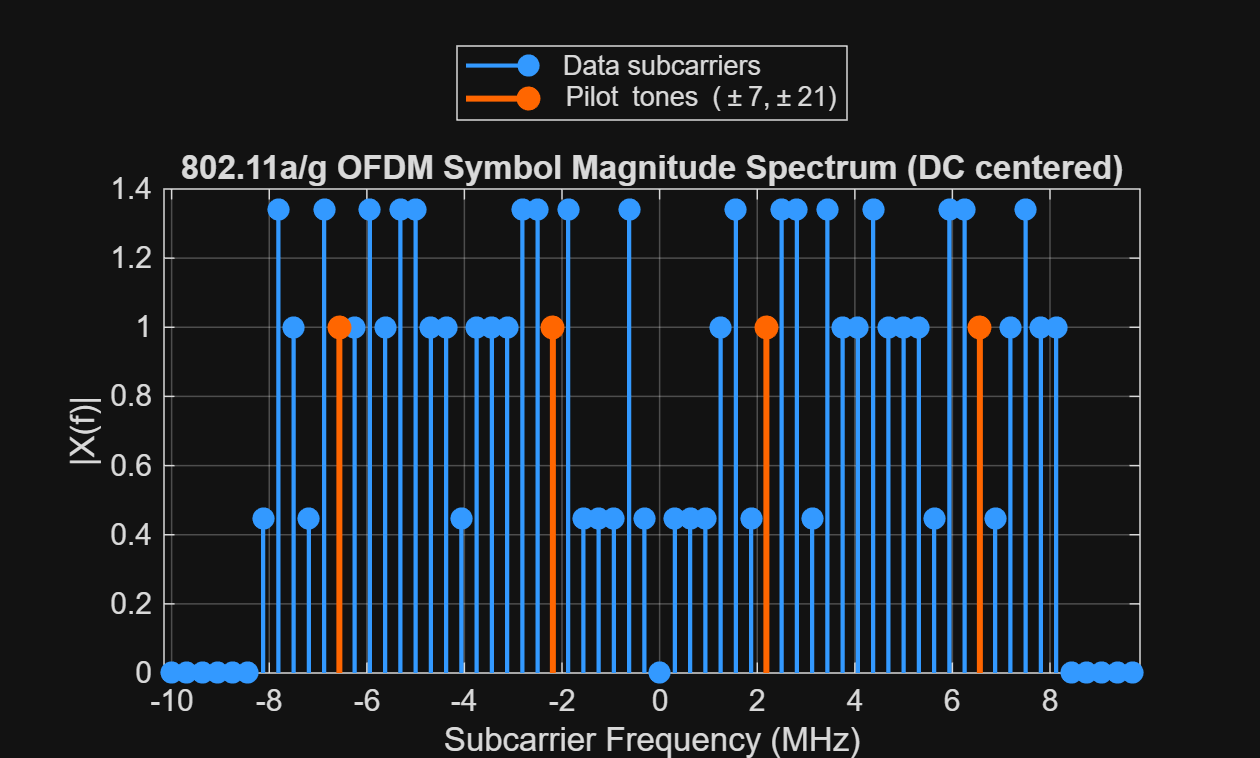

N  = 64;  % FFT size
Fs = 20e6;  % sampling rate (Hz)
dF = Fs/N;  % subcarrier spacing (Hz)

sc_all = (-N/2):(N/2-1);  % -32-31
pilot_sc = [-21, -7, 7, 21];
data_sc = [-26:-22, -20:-8, -6:-1, 1:6, 8:20, 22:26];
dc_sc = 0;

% Modulation mappings
mapBPSK  = @(b) (1 - 2*b(:));                     % {+1,-1}
%map16QAM = @(B) ((1-2*B(:,1)).*(2-(1-2*B(:,2))) + ...
 %                1j*(1-2*B(:,3)).*(2-(1-2*B(:,4))))/sqrt(10); % Gray 16-QAM, Es=1
bits2qam16 = @(bits) qammod( ...
    bi2de(reshape(bits, 4, []).', 'left-msb'), ... % symbol indices
    16, 'gray', 'UnitAveragePower', true);

% Generate symbols
n_pil = numel(pilot_sc);
n_dat = numel(data_sc);
pilot_bits = randi([0 1], n_pil, 1);
data_bits = randi([0 1], n_dat*4, 1);
pilots = mapBPSK(pilot_bits);
%data_syms = map16QAM(reshape(data_bits, [], 4));
data_syms = bits2qam16(data_bits);
% Build frequency-domain vector (fftshifted layout)
X_original = zeros(1, N);
X_original(ismember(sc_all, pilot_sc)) = pilots;
X_original(ismember(sc_all, data_sc)) = data_syms;

% Frequency axis in MHz with DC centered
f_axis_MHz = sc_all * (dF/1e6);

% Plot magnitude spectrum; highlight pilots
figure; hold on; grid on; box on;
stem(f_axis_MHz, abs(X_original), ...
     'Marker', 'o', 'MarkerFaceColor', [0.2 0.6 1], 'Color', [0.2 0.6 1], 'LineWidth', 1.4);

pilot_mask = ismember(sc_all, pilot_sc);
stem(f_axis_MHz(pilot_mask), abs(X_original(pilot_mask)), ...
     'Marker', 'o', 'MarkerFaceColor', [1 0.4 0], 'Color', [1 0.4 0], 'LineWidth', 2);

xlabel('Subcarrier Frequency (MHz)');
ylabel('|X(f)|');
title('802.11a/g OFDM Symbol Magnitude Spectrum (DC centered)');
legend('Data subcarriers','Pilot tones (\pm7,\pm21)', ...
       'Location','northoutside');
xlim([(min(sc_all)-0.5) (max(sc_all)+0.5)] * (dF/1e6));

## (2) subcarrier spacing

fprintf("subcarrier spacing = %f Hz", dF);

subcarrier spacing = 312500.000000 Hz

Same as stated in the standard (312.5 kHz)

## (3) OFDM time domain signals

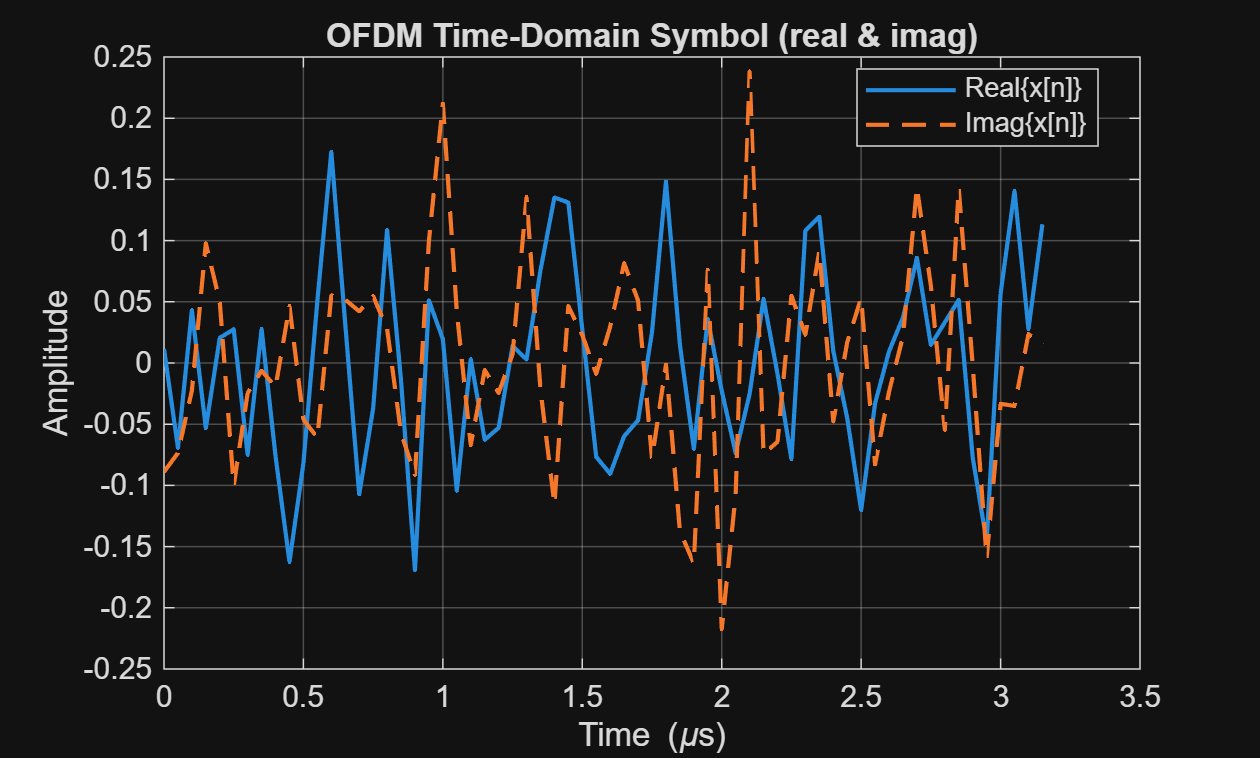

x_sL = ifft(ifftshift(X_original), N);   % one OFDM symbol, no cyclic prefix

% Time axis in microseconds
t_us = (0:N-1)/Fs * 1e6;

% Plot real and imaginary parts
figure; hold on; grid on; box on;
plot(t_us, real(x_sL), '-', 'LineWidth', 1.4); 
plot(t_us, imag(x_sL), '--', 'LineWidth', 1.4);
xlabel('Time (\mus)'); ylabel('Amplitude');
title('OFDM Time-Domain Symbol (real & imag)');
legend('Real\{x[n]\}','Imag\{x[n]\}','Location','best');

## (4) Add Cyclic prefix

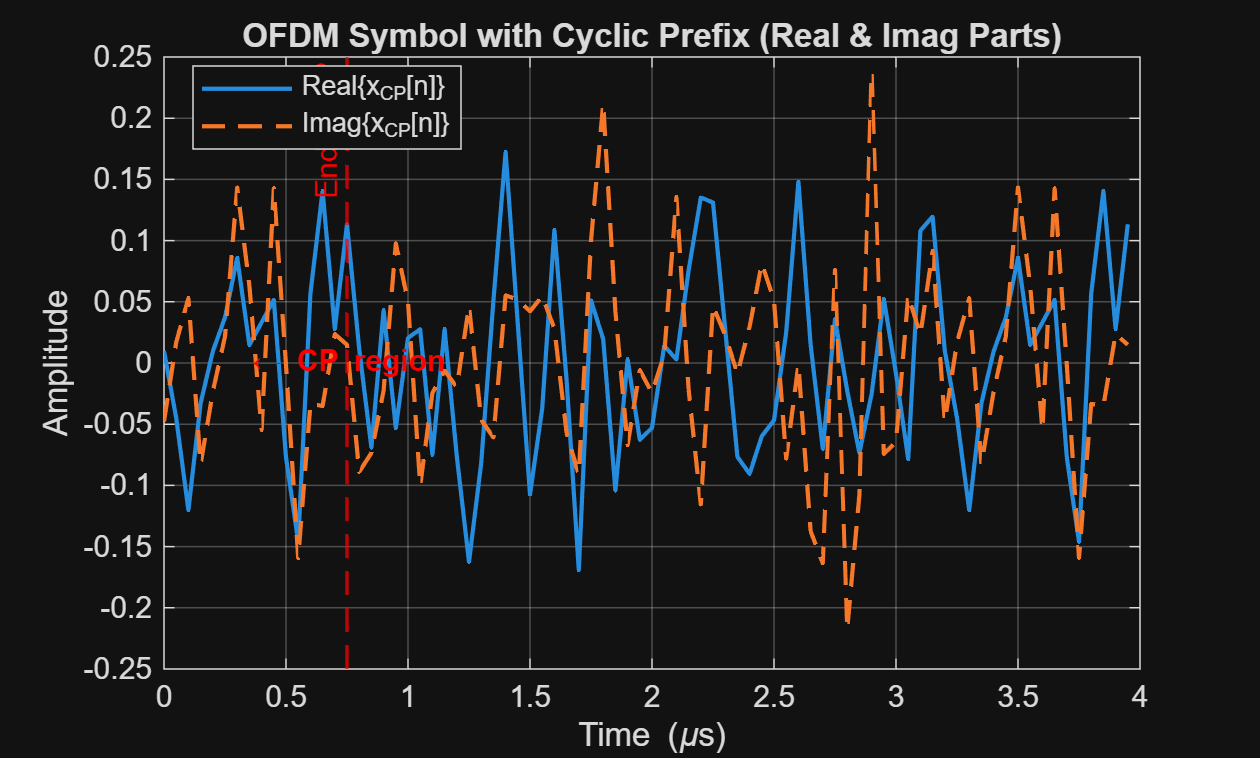

Ncp = 16; % cyclic prefix length
x_cp = [x_sL(end-Ncp+1:end), x_sL];

% Time axis in microseconds
t_us = (0:length(x_cp)-1)/Fs * 1e6;

% Plot with CP marked
figure; hold on; grid on; box on;
plot(t_us, real(x_cp), '-', 'LineWidth', 1.4);
plot(t_us, imag(x_cp), '--', 'LineWidth', 1.4);
xline(t_us(Ncp), 'r--', 'LineWidth', 1.2, 'Label', 'End of CP', 'LabelHorizontalAlignment','left');
xlabel('Time (\mus)');
ylabel('Amplitude');
title('OFDM Symbol with Cyclic Prefix (Real & Imag Parts)');
legend('Real\{x_{CP}[n]\}', 'Imag\{x_{CP}[n]\}', 'Location', 'best');
text(t_us(Ncp/2), 0, '\leftarrow CP region', 'Color', 'r', 'FontWeight', 'bold', 'HorizontalAlignment','left');

## (5) Duration of OFDM symbol

T_symbol = N*(1/Fs) * 1e6;
T_symbol_cp = (N+Ncp)*(1/Fs) *1e6;
fprintf("OFDM symbol duration without cyclic prefix = %.1f us", T_symbol);

OFDM symbol duration without cyclic prefix = 3.2 us

fprintf("OFDM symbol duration with cyclic prefix = %.1f us", T_symbol_cp);

OFDM symbol duration with cyclic prefix = 4.0 us

## (6) Received signal with no noise

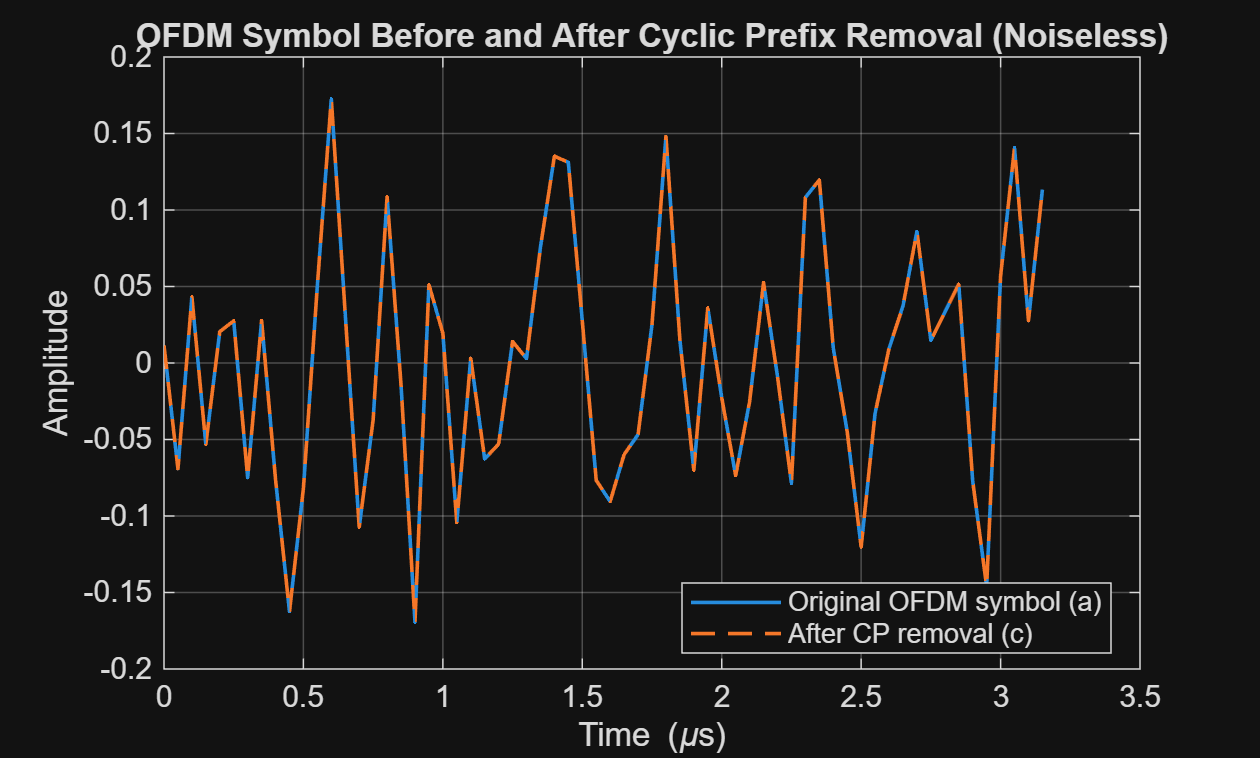

x_received = x_cp;
x_received_nocp = x_received(Ncp+1:end);

t_a = (0:N-1)/Fs * 1e6; 
t_c = (0:N-1)/Fs * 1e6;

figure; hold on; grid on; box on;
plot(t_a, real(x_sL), '-', 'LineWidth', 1.2);
plot(t_c, real(x_received_nocp), '--', 'LineWidth', 1.2);
xlabel('Time (\mus)');
ylabel('Amplitude');
title('OFDM Symbol Before and After Cyclic Prefix Removal (Noiseless)');
legend('Original OFDM symbol (a)','After CP removal (c)','Location','best');

## (7) Received Symbols

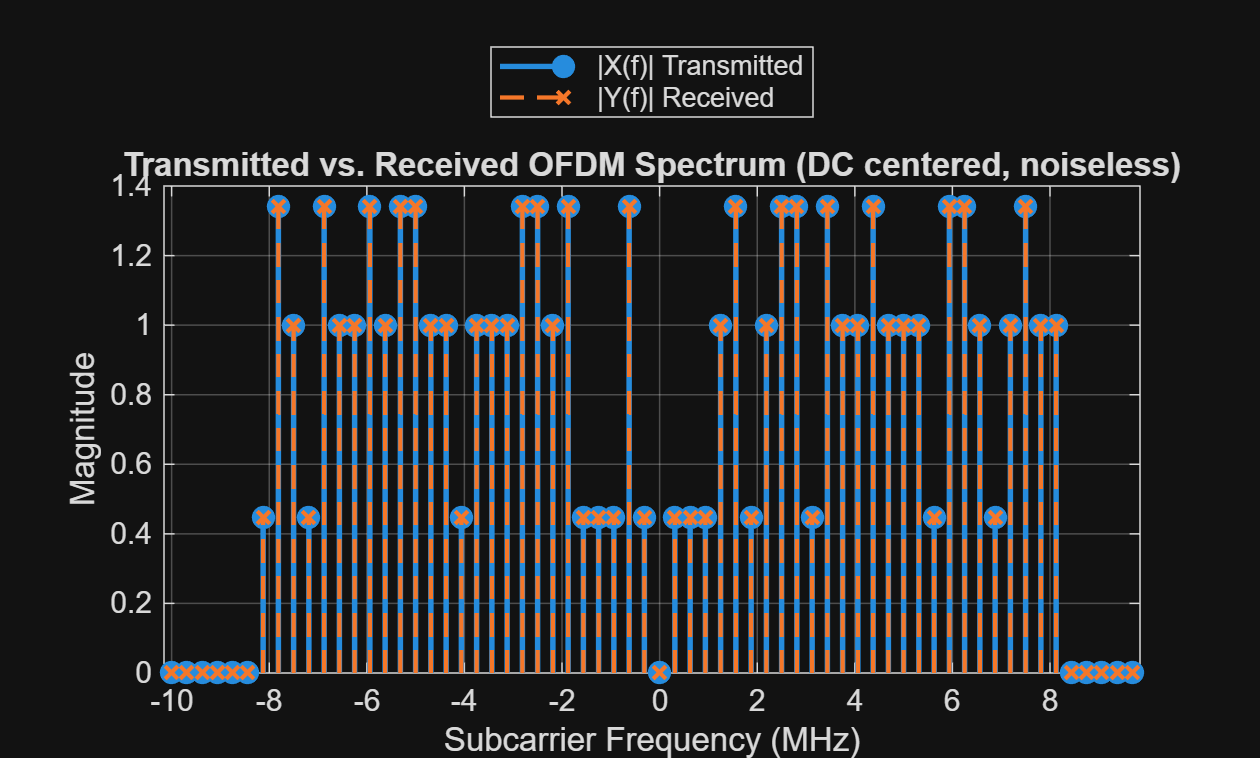

X_received_nocp = fftshift(fft(x_received_nocp, N));

f_MHz = sc_all * (dF/1e6);
figure; hold on; grid on; box on;
stem(f_MHz, abs(X_original), 'filled', 'Marker', 'o', 'LineWidth', 1.8 );   % transmitted
stem(f_MHz, abs(X_received_nocp), 'Marker', 'x', 'LineWidth', 1.4, 'LineStyle','--');             % received
xlabel('Subcarrier Frequency (MHz)'); ylabel('Magnitude');
title('Transmitted vs. Received OFDM Spectrum (DC centered, noiseless)');
legend('|X(f)| Transmitted','|Y(f)| Received','Location','northoutside');
xlim([(min(sc_all)-0.5) (max(sc_all)+0.5)] * (dF/1e6));

The received symbols are identical to the original generated ones.

## (8) Peak-to-Average Power Ratio

x_all = complex([],[]);
num_Syms = 1000;
for k = 1:num_Syms
    pilots = mapBPSK(randi([0 1], numel(pilot_sc), 1));
    bits = randi([0 1], numel(data_sc)*4, 1);
    data16 = bits2qam16(bits);
    Xf = zeros(1, N);
    Xf(ismember(sc_all, pilot_sc)) = pilots;
    Xf(ismember(sc_all, data_sc)) = data16;
    x_sL = ifft(ifftshift(Xf), N);

    % Accumulate
    x_all = [x_all, x_sL]; %#ok<AGROW>
end

% Power metrics (no CP)
p_samples = abs(x_all).^2;
P_peak = max(p_samples);
P_avg  = mean(p_samples);
PAPR = P_peak / P_avg;
PAPR_dB = 10*log10(PAPR);

fprintf('Over %d OFDM symbols (no CP):\n', num_Syms);

Over 1000 OFDM symbols (no CP):


fprintf('  Peak power = %.6f\n', P_peak);

  Peak power = 0.148621


fprintf('  Average power = %.6f\n', P_avg);

  Average power = 0.012668


fprintf('  PAPR = %.4f (linear) = %.2f dB\n', PAPR, PAPR_dB);

  PAPR = 11.7324 (linear) = 10.69 dB


## (9) SNR = 15dB

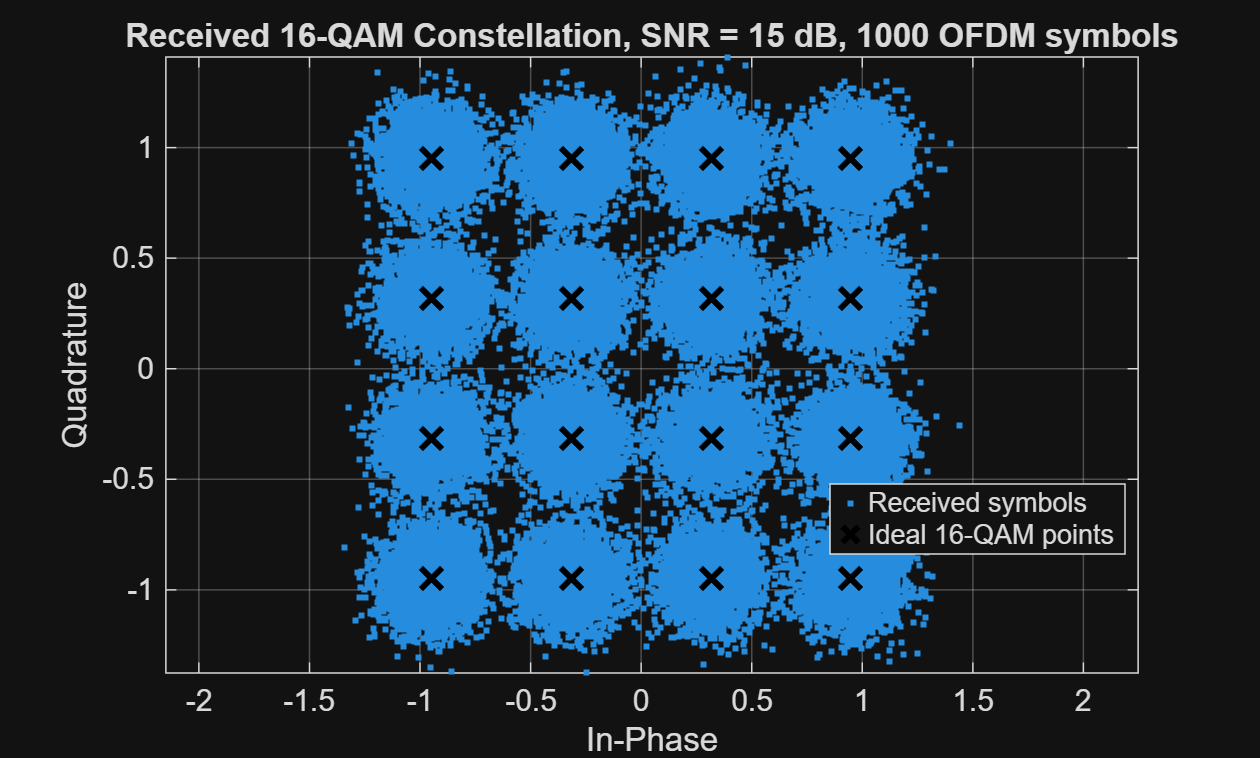

SNRdB = 15;
SNRlin = 10^(SNRdB/10);
num_Syms = 1000;
X_received_all = complex(zeros(num_Syms*numel(data_sc),1));

wr = 1;

signal_all = [];
noise_all  = [];

for k = 1:num_Syms
    % TX
    pilots = mapBPSK(randi([0 1], numel(pilot_sc), 1));
    bits   = randi([0 1], numel(data_sc)*4, 1);
    data16 = bits2qam16(bits);

    Xf = zeros(1, N);
    Xf(ismember(sc_all, pilot_sc)) = pilots;
    Xf(ismember(sc_all, data_sc))  = data16;
    x_sL = ifft(ifftshift(Xf), N);
    x_cp = [x_sL(end-Ncp+1:end), x_sL];

    % AWGN channel
    sigPwr = mean(abs(x_cp).^2);
    N0 = sigPwr / SNRlin; % E{|w|^2}
    channel_noise = sqrt(N0/2) * (randn(size(x_cp)) + 1j*randn(size(x_cp)));
    x_received = x_cp + channel_noise;

    % RX
    x_received_nocp = x_received(Ncp+1:end);
    X_received_nocp = fftshift(fft(x_received_nocp, N));  
    X_received_data = X_received_nocp(ismember(sc_all, data_sc));

    X_received_all(wr:wr+numel(data_sc)-1) = X_received_data(:);
    wr = wr + numel(data_sc);

    signal_all = [signal_all, x_cp]; %#ok<AGROW>
    noise_all = [noise_all, channel_noise];    %#ok<AGROW>
end

% Ideal 16-QAM constellation for reference
cI = [-3 -1 1 3]; cQ = [-3 -1 1 3];
[CI,CQ] = meshgrid(cI,cQ);
const = (CI(:) + 1j*CQ(:))/sqrt(10);

figure; hold on; grid on; box on;
plot(real(X_received_all), imag(X_received_all), '.', 'MarkerSize', 6);                 % received points
plot(real(const), imag(const), 'kx', 'MarkerSize', 10, 'LineWidth', 2); % ideal refs

axis equal;
xlabel('In-Phase'); ylabel('Quadrature');
title(sprintf('Received 16-QAM Constellation, SNR = %d dB, %d OFDM symbols', SNRdB, num_Syms));
legend('Received symbols','Ideal 16-QAM points','Location','best');

## (10) SNR verification 

SNRdB_ideal = 15;
P_signal = mean(abs(signal_all).^2);
P_noise  = mean(abs(noise_all).^2);
SNR_measured_lin = P_signal / P_noise;
SNR_measured_dB  = 10*log10(SNR_measured_lin);

fprintf('Measured SNR over %d OFDM symbols:\n', num_Syms);

Measured SNR over 1000 OFDM symbols:


fprintf('Target SNR = %.2f dB\n', SNRdB_ideal);

Target SNR = 15.00 dB


fprintf('Measured SNR = %.2f dB\n', SNR_measured_dB);

Measured SNR = 14.99 dB


The resulting SNR is very close to the 15dB setting

## (11) Different SNR values

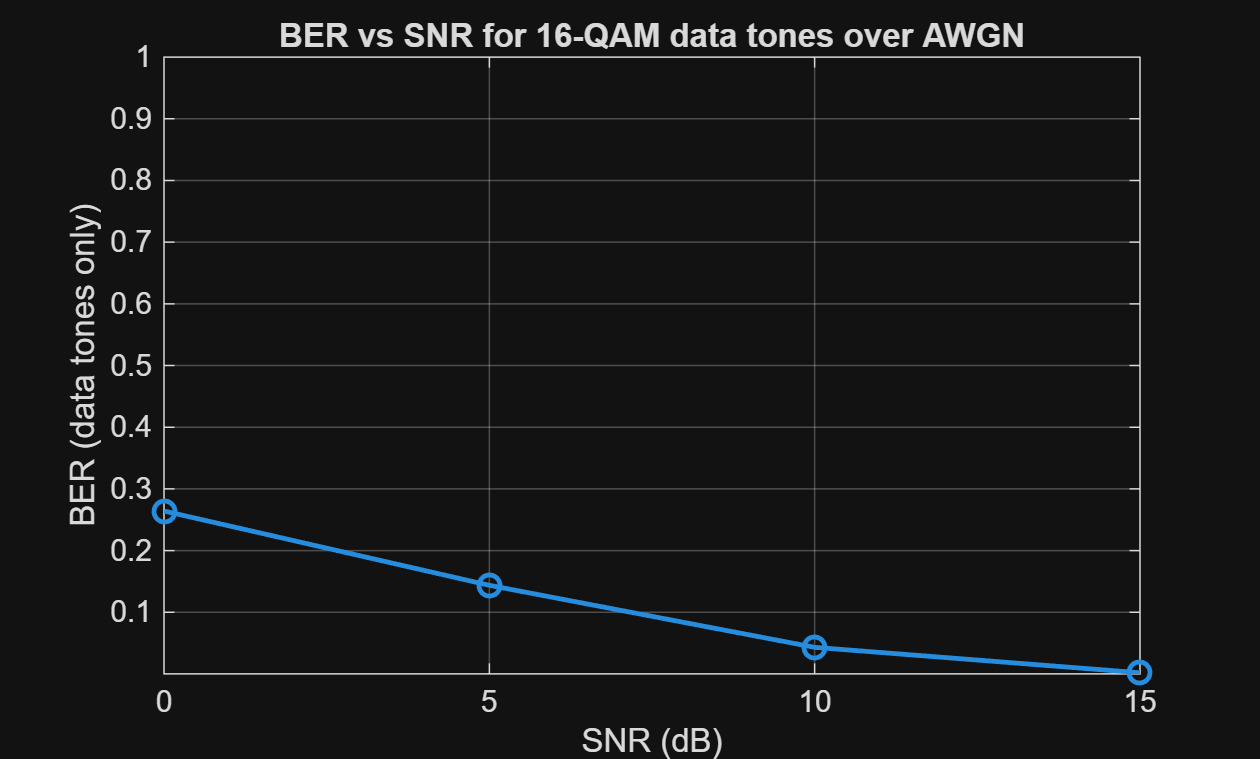

SNRdB_list = [0 5 10 15];

gray_bits = [0 0; 0 1; 1 1; 1 0];   % Gray per axis for levels [-3 -1 1 3]
pam_bits = gray_bits;

mask_pilot = ismember(sc_all, pilot_sc);
mask_data = ismember(sc_all, data_sc);
n_dat = numel(data_sc);

BER = zeros(size(SNRdB_list));

for si = 1:numel(SNRdB_list)
    SNRlin = 10^(SNRdB_list(si)/10);

    err_bits = 0;
    tot_bits = num_Syms*n_dat*4;

    for ksym = 1:num_Syms
        % TX
        pilots = mapBPSK(randi([0 1], numel(pilot_sc), 1));
        %bits = randi([0 1], n_dat*4, 1);
        %data16 = map16QAM(reshape(bits, [], 4));  % n_dat x 1 complex
        bits = randi([0 1], n_dat*4, 1);
        symIdx = bi2de(reshape(bits, 4, []).', 'left-msb');
        data16 = qammod(symIdx, 16, 'gray', 'UnitAveragePower', true);
        %B = reshape(bits, [], 4);            % n_dat x 4  [bI1 bI0 bQ1 bQ0]
        
        % Map I and Q bit pairs from level to to Gray 4-PAM bits
        %[~, idxI] = ismember(B(:,1:2), pam_bits, 'rows');   % n_dat x 1 indices in 1..4
        %[~, idxQ] = ismember(B(:,3:4), pam_bits, 'rows');   % n_dat x 1
        %data16 = (pam_levels(idxI).' + 1j*pam_levels(idxQ).') / sqrt(10);

        Xf = zeros(1, N);
        Xf(mask_pilot) = pilots;
        Xf(mask_data) = data16;
        x_original = ifft(ifftshift(Xf), N);
        x_cp = [x_original(end-Ncp+1:end), x_original];

        % AWGN channel
        sigPwr = mean(abs(x_cp).^2);
        N0 = sigPwr / SNRlin;
        channel_noise = sqrt(N0/2) * (randn(size(x_cp)) + 1j*randn(size(x_cp)));
        x_received = x_cp + channel_noise;

        % RX
        x_received_nocp = x_received(Ncp+1:end);
        X_received_nocp = fftshift(fft(x_received_nocp, N));
        X_received_data = X_received_nocp(mask_data);

        % Nearest-neighbor 16-QAM detection -> bits
        %rx_bits = zeros(n_dat,4);
        %for n=1:n_dat
        %    [~,idx] = min(abs(X_received_data(n) - const));
        %    rx_bits(n,:) = label_bits(idx,:);
        %end
        
        rx_bits_mat = qamdemod(X_received_data, 16, 'gray', ...
                       'UnitAveragePower', true, 'OutputType', 'bit'); 
        rx_bits = reshape(rx_bits_mat, [], 1);   
        err_bits = err_bits + sum(rx_bits ~= bits);
    end

    BER(si) = err_bits / tot_bits;
end

% ---- Plot BER vs SNR ----
figure; grid on; box on; hold on;
semilogy(SNRdB_list, BER, '-o', 'LineWidth', 1.6, 'MarkerSize', 7);
xlabel('SNR (dB)'); ylabel('BER (data tones only)');
title(sprintf('BER vs SNR for 16-QAM data tones over AWGN'));
ylim([1e-4 1]); xlim([min(SNRdB_list) max(SNRdB_list)]);

As SNR gets higher, the original signal dominants the received signal, and thus getting a BER closer to 0.

## [Part 2]

## (1) STS generation

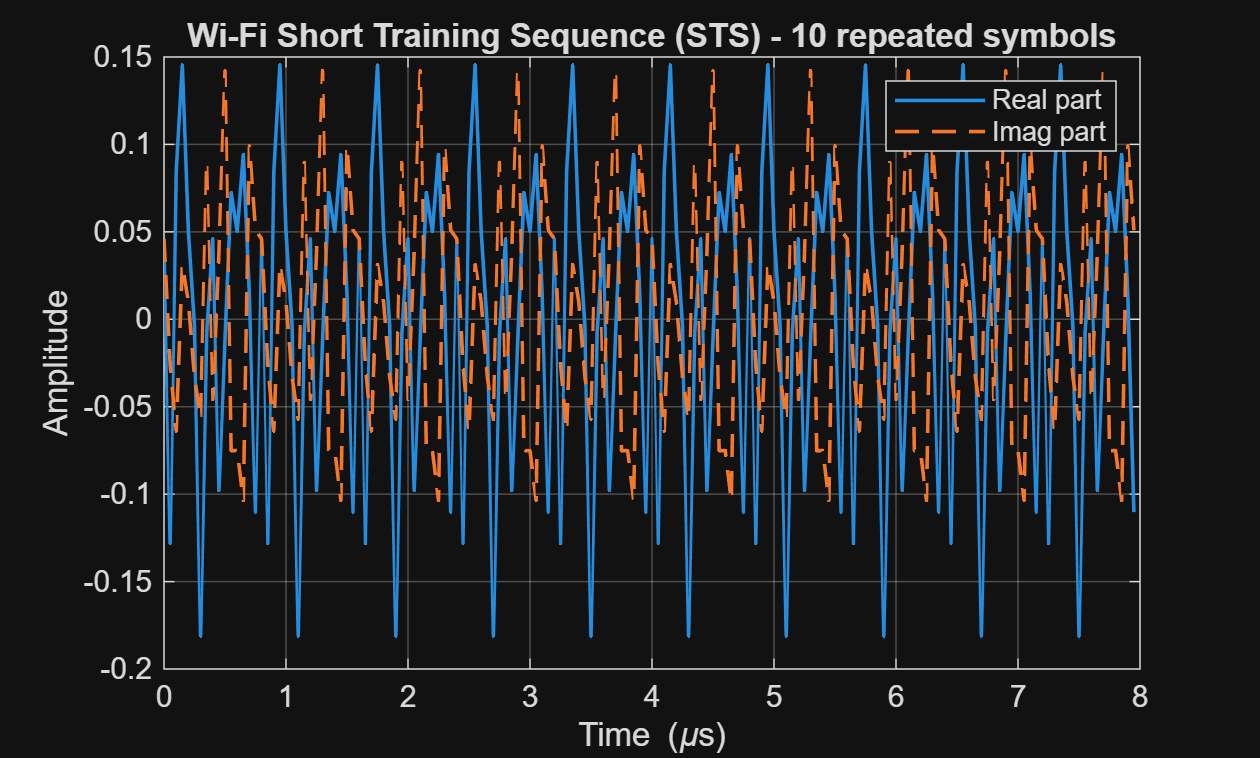

clear; clc;

N  = 64;     
Fs = 20e6;  
dF = Fs/N;  
n_rep_STS = 10;  

sc_all = (-N/2):(N/2-1);
active_sc = -26:26; 
Xf = zeros(1, N);

% STS from course
STS_base = sqrt(13/6)*[...
    0 0 1+1j 0 0 0 -1-1j 0 0 0 1+1j 0 0 0 -1-1j 0 0 0 -1-1j 0 0 0 1+1j ...
    0 0 0 0 0 0 0 -1-1j 0 0 0 -1-1j 0 0 0 1+1j 0 0 0 1+1j 0 0 0 1+1j 0 0 0 1+1j 0 0];

active_bins = find(ismember(sc_all, active_sc));
X_STS(active_bins) = STS_base;        

sts_symbol = ifft(ifftshift(X_STS), N); 
%sts_symbol = sts_symbol / max(abs(sts_symbol)); 

% x10
sts_time = repmat(sts_symbol(1:16), 1, n_rep_STS);   % each short symbol = 16 samples
t_us = (0:length(sts_time)-1)/Fs * 1e6;

% ----- Plot -----
figure; hold on; grid on; box on;
plot(t_us, real(sts_time), '-',  'LineWidth', 1.2);
plot(t_us, imag(sts_time), '--', 'LineWidth', 1.2);
xlabel('Time (\mus)'); ylabel('Amplitude');
title('Wi-Fi Short Training Sequence (STS) - 10 repeated symbols');
legend('Real part','Imag part');

## (2) LTS generation

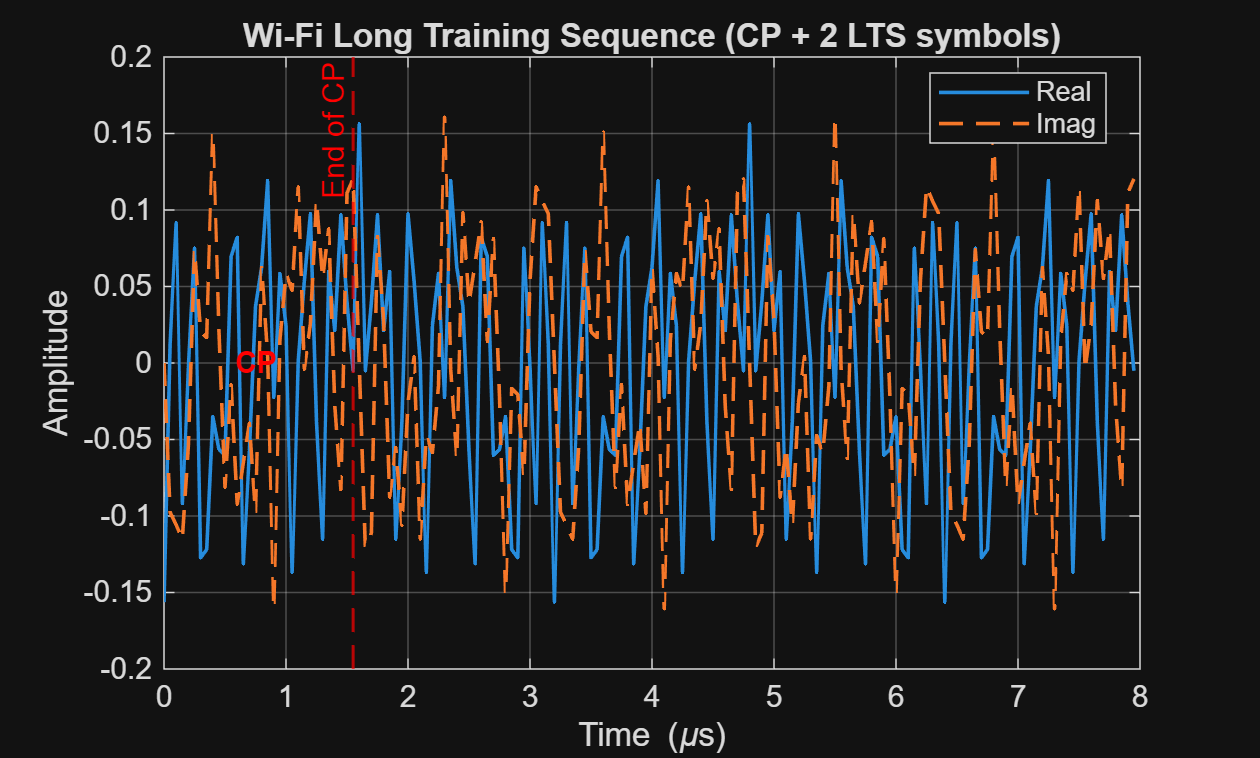

Ncp_LTS = 32;
LTS_base = [ ...
    1, 1, -1, -1, 1, 1, -1, 1, -1, 1, 1, 1, 1, 1, 1, -1, -1, 1, 1, -1, 1, -1, 1, 1, 1, 1, ...
    0, ...
    1, -1, -1, 1, 1, -1, 1, -1, 1, -1, -1, -1, -1, -1, 1, 1, -1, -1, 1, -1, 1, -1, 1, 1, 1, 1];

X_LTS = zeros(1,N);
active_bins = find(ismember(sc_all, active_sc));
X_LTS(active_bins) = LTS_base;
lts_sym = ifft(ifftshift(X_LTS), N);

% add cp for total 2 data pieces
cp  = lts_sym(end-Ncp_LTS+1:end);
lts_time = [cp, lts_sym, lts_sym];

t_us = (0:numel(lts_time)-1)/Fs*1e6;

% Plot real/imag parts
figure; hold on; grid on; box on;
plot(t_us, real(lts_time), '-', 'LineWidth', 1.2);
plot(t_us, imag(lts_time), '--', 'LineWidth', 1.2);
xlabel('Time (\mus)'); ylabel('Amplitude');
title('Wi-Fi Long Training Sequence (CP + 2 LTS symbols)');
legend('Real','Imag','Location','best');

xline(t_us(Ncp_LTS),   'r--', 'LineWidth', 1, 'Label', 'End of CP', 'LabelHorizontalAlignment','left', 'HandleVisibility','off'); 
text(t_us(round(Ncp_LTS/2)), 0, ' CP ', 'HorizontalAlignment','center','FontWeight','bold', 'Color', 'r');

## (3) Frame of STS+LTS+OFDMx5

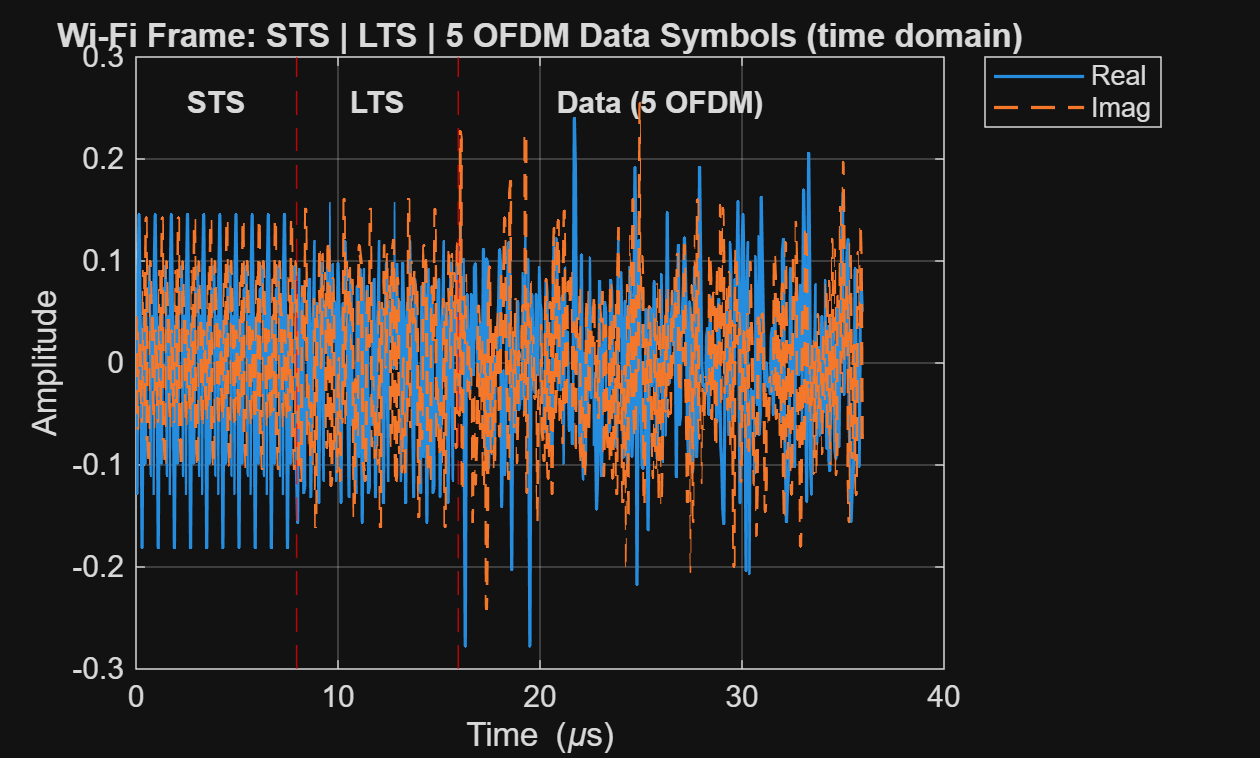

sc_all = (-N/2):(N/2-1);
pilot_sc = [-21 -7 7 21];
data_sc = [-26:-22 -20:-8 -6:-1 1:6 8:20 22:26];
Ncp_data = 16;
num_data_syms = 5;
bits_per_sym = 48*4;

mapBPSK = @(b) 1-2*b(:);
% Gray 16-QAM via Gray 4-PAM on I/Q
pam_levels = [-3 -1 1 3];
pilot_tones = ismember(sc_all,pilot_sc); 
data_tones = ismember(sc_all,data_sc); 
n_data = numel(data_sc);
DATA_time = complex([],[]);

bits2qam16 = @(bits) qammod( ...
    bi2de(reshape(bits, 4, []).', 'left-msb'), ... % symbol indices
    16, 'gray', 'UnitAveragePower', true);

total_tx_data_bits = zeros(num_data_syms*bits_per_sym,1);
wptr = 1;
for k = 1:5
    pilots = mapBPSK(randi([0 1],nnz(pilot_tones),1)).';
    % data bits -> 16-QAM (Gray)
    bits = randi([0 1], n_data*4, 1); 
    symIdx = bi2de(reshape(bits, 4, []).', 'left-msb');
    data16 = qammod(symIdx, 16, 'gray', 'UnitAveragePower', true);
    total_tx_data_bits(wptr:wptr+bits_per_sym-1) = bits;
    wptr = wptr + bits_per_sym;

    Xf = zeros(1,N); 
    Xf(pilot_tones)=pilots; 
    Xf(data_tones)=data16;
    x = ifft(ifftshift(Xf),N);
    xcp = [x(end-Ncp_data+1:end), x];     % 80 samples
    DATA_time = [DATA_time, xcp]; %#ok<AGROW>
end

frame = [sts_time, lts_time, DATA_time];
% Power normalization
% frame = frame / sqrt(mean(abs(frame).^2));
t_us = (0:numel(frame)-1)/Fs*1e6;

%plot
figure; hold on; grid on; box on;
plot(t_us, real(frame), 'LineWidth', 1.1, 'DisplayName','Real');
plot(t_us, imag(frame), '--', 'LineWidth', 1.1, 'DisplayName','Imag');

% Region boundaries
idx_STS_end = numel(sts_time);
idx_LTS_end = idx_STS_end + numel(lts_time);
xline(t_us(idx_STS_end), 'r--', 'HandleVisibility','off');
xline(t_us(idx_LTS_end), 'r--', 'HandleVisibility','off');

% Region labels
yl = ylim;
text(t_us(round(idx_STS_end/2)), 0.85*yl(2), 'STS', 'HorizontalAlignment','center','FontWeight','bold');
text(t_us(round((idx_STS_end+idx_LTS_end)/2)), 0.85*yl(2), 'LTS', 'HorizontalAlignment','center','FontWeight','bold');
text(t_us(round((idx_LTS_end+numel(frame))/2)), 0.85*yl(2), 'Data (5 OFDM)', 'HorizontalAlignment','center','FontWeight','bold');

xlabel('Time (\mus)'); ylabel('Amplitude');
title('Wi-Fi Frame: STS | LTS | 5 OFDM Data Symbols (time domain)');
legend('Location','northeastoutside');

## (4) Match filter

let $s^*[k]$ be the conjugated and reversed time domain signal of 1/10 STS signal (STS signal is consisted of 10 such pieces), and $r[n]
$ is the received time sequence.

let $y[n] = \sum_{k=0}^{k=15}r[n-k]s^*[k]
$, (convolution of r and s*)

and $z[n] = \sum_{i=0}^{i=9}y[n+16i]
$

Find $n$ s.t. $z[n]$ has maximum value, then $n$ is the start of STS, we can then add the corresponding time delay to obtain the start of LTS and data frames.

The reason why we choose the conjugated and reversed signal as matched filter is that when conducting convolution, we will reverse the time signal of one of the signal, and the filter will then be identical to the original signal and thus obtaining max peak value.

## (5) Zero padding noise

ST_len = 16;
num_data_syms = 5;
sts_len = 10*ST_len;
lts_len = Ncp_LTS + 2*N;

zeropad_len = 30;
true_frame_start = zeropad_len+1;
true_lts_start = true_frame_start+sts_len;
true_data_start = true_lts_start+lts_len;

x_received = [zeros(1, zeropad_len), frame, zeros(1, zeropad_len)];
sts_piece = sts_symbol(1:16);
%y = filter(conj(fliplr(sts_piece)), 1, x_received);
s = conj(fliplr(sts_piece));
y_full = conv(x_received, s, 'full');
y = y_full(1:length(x_received));

comb = zeros(1, sts_len);
comb(1:ST_len:end) = 1;
z = conv(y, comb, 'full');
z = z(sts_len:end);
[~, z_max_index] = max(z);
idx_sts = z_max_index;

idx_lts_cp = idx_sts + sts_len; 
idx_data = idx_lts_cp + lts_len;

t = (0:length(x_received)-1)/Fs*1e6;
figure; hold on; grid on; box on;
plot(t, z, '--', 'LineWidth', 1.0, 'DisplayName','Comb score z[n] (norm)');

plot(t, x_received, '--', 'LineWidth', 1.2, 'DisplayName','x_received')

plot(t, y, 'LineWidth', 1.2, 'DisplayName','STS MF metric y[n] (norm)');

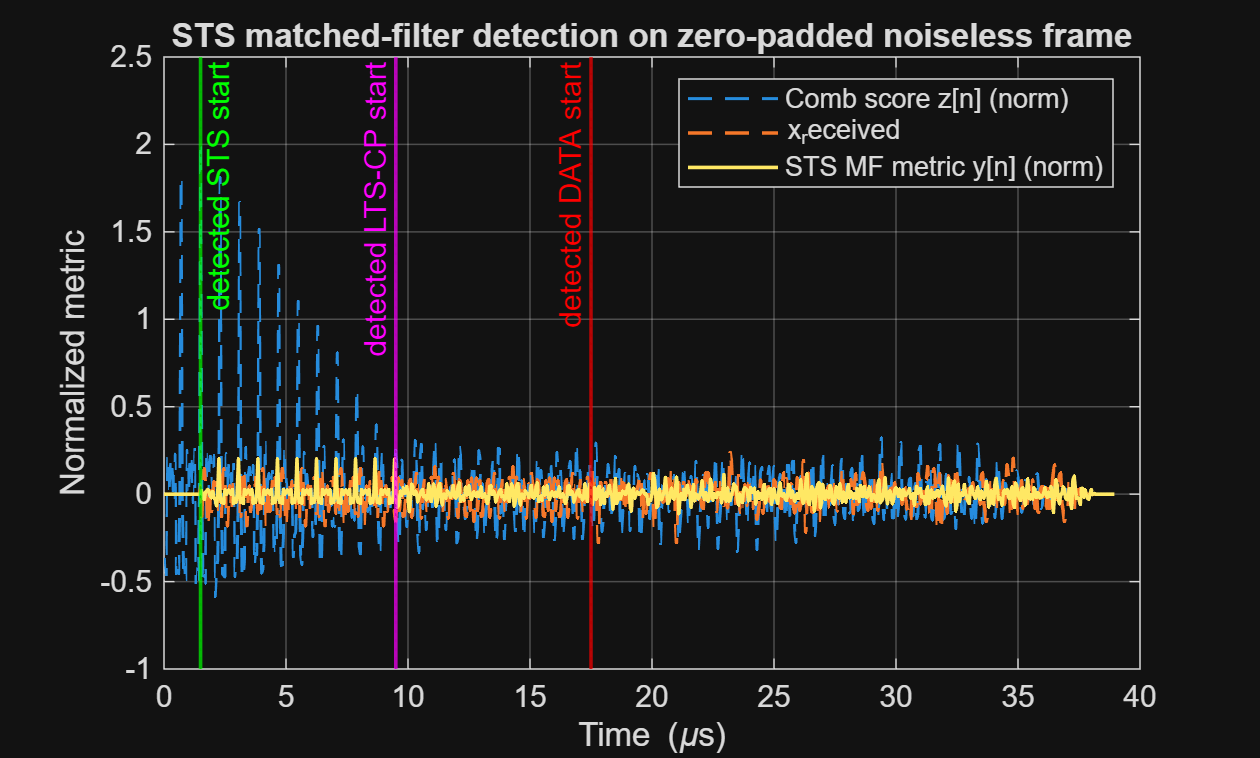



% Truth (no legend)
xline(t(true_frame_start), 'k:', 'HandleVisibility','off');
xline(t(true_lts_start),   'k:', 'HandleVisibility','off');
xline(t(true_data_start),  'k:', 'HandleVisibility','off');

% Detected (no legend entries)
xline(t(max(idx_sts,1)),    'g-', 'LineWidth',1.2, 'Label','detected STS start', ...
    'LabelHorizontalAlignment','right','HandleVisibility','off');
xline(t(max(idx_lts_cp,1)), 'm-', 'LineWidth',1.2, 'Label','detected LTS-CP start', ...
    'LabelHorizontalAlignment','left','HandleVisibility','off');
xline(t(max(idx_data,1)),   'r-', 'LineWidth',1.2, 'Label','detected DATA start', ...
    'LabelHorizontalAlignment','left','HandleVisibility','off');

xlabel('Time (\mus)'); ylabel('Normalized metric');
title('STS matched-filter detection on zero-padded noiseless frame');
legend('Location','best');

We can se that the result of STS matched filter has several periodic peaks like a comb in the STS region as expected (yellow curve), and the comb filter will match those periodic spike and find the starting index of STS. 

% Print offsets (should be 0 in noiseless test)
fprintf('Detected vs GT offsets (samples):\n');

Detected vs GT offsets (samples):


fprintf('  STF start : %d\n', idx_sts - true_frame_start);

  STF start : 0


fprintf('  LTS start : %d\n', idx_lts_cp - true_lts_start);

  LTS start : 0


fprintf('  DATA start: %d\n', idx_data   - true_data_start);

  DATA start: 0


Yes it correctly identify the beginning of the frame.

We can tell that directly from the figure above, the detected STS start is exactly the start of the original received frame after zero padding.

## (6) Decode

cI = [-3 -1 1 3]; cQ = [-3 -1 1 3];
[CI,CQ] = meshgrid(cI,cQ);
const = (CI(:) + 1j*CQ(:))/sqrt(10);    
[~,iidx]=ismember(CI(:),cI); [~,qidx]=ismember(CQ(:),cQ);

rx_bits_all = []; 
rx_sym_errors = 0; 
total_syms = 0;

total_rx_data_bits = zeros(num_data_syms*bits_per_sym,1);
rptr = 1;

for k = 0:4
    each_frame_start = idx_data + k*(N+Ncp_data);
    x_data_with_cp = x_received(each_frame_start:each_frame_start+N+Ncp_data-1);
    x_data_nocp = x_data_with_cp(Ncp_data+1:end);

    X_nocp = fftshift(fft(x_data_nocp, N));
    X_nocp_data = X_nocp(data_tones);
    %X_nocp_data = X_nocp_data/sqrt(10);
    rx_bits_mat = qamdemod( ...
        X_nocp_data, 16, 'gray', ...
        'UnitAveragePower', true, 'OutputType', 'bit'); 
    %rx_bits_mat = reshape(rx_bits_mat, 4, []).';
    rx_bits = reshape(rx_bits_mat, [], 1);
    total_rx_data_bits(rptr:rptr+bits_per_sym-1) = rx_bits(:);
    rptr = rptr + bits_per_sym;
end

BER = mean(total_rx_data_bits ~= total_tx_data_bits);
fprintf('BER over 5 OFDM symbols = %.4g\n', BER);

BER over 5 OFDM symbols = 0


The overall bit error rate = 0.

## (7) Noisy Channel

%% Zero-padded frame + AWGN @ 0 dB SNR, STS-only detection
ST_len = 16;
sts_len = 10*ST_len;
lts_len = Ncp_LTS + 2*N;

zeropad_len = 30;
true_frame_start = zeropad_len+1;
true_lts_start  = true_frame_start + sts_len;
true_data_start = true_lts_start + lts_len;

% --- Build zero-padded received stream (clean) ---
x_received_clean = [zeros(1, zeropad_len), frame, zeros(1, zeropad_len)];

% --- Add complex AWGN for 0 dB SNR (relative to average power of the frame) ---
SNRdB = 0; SNRlin = 10^(SNRdB/10);
sigPwr_frame = mean(abs(frame).^2);                   % average power of the non-zero frame
N0 = sigPwr_frame / SNRlin;                           % E{|w|^2}
w  = sqrt(N0/2) * (randn(size(x_received_clean)) + 1j*randn(size(x_received_clean)));
x_received = x_received_clean + w;                    % noisy stream

sts_piece = sts_symbol(1:16);
s = conj(fliplr(sts_piece));
y_full = conv(x_received, s, 'full');
y = y_full(1:length(x_received));

comb = zeros(1, sts_len);
comb(1:ST_len:end) = 1;
z = conv(y, comb, 'full');
z = z(sts_len:end);
[~, z_max_index] = max(z);
idx_sts = z_max_index;

idx_lts_cp = idx_sts + sts_len; 
idx_data = idx_lts_cp + lts_len;

t = (0:length(x_received)-1)/Fs*1e6;
figure; hold on; grid on; box on;
plot(t, z, '--', 'LineWidth', 1.0, 'DisplayName','Comb score z[n] (norm)');

plot(t, x_received, 'LineWidth', 1.2, 'DisplayName','x_received');

plot(t, y, 'LineWidth', 1.2, 'DisplayName','STS MF metric y[n] (norm)');

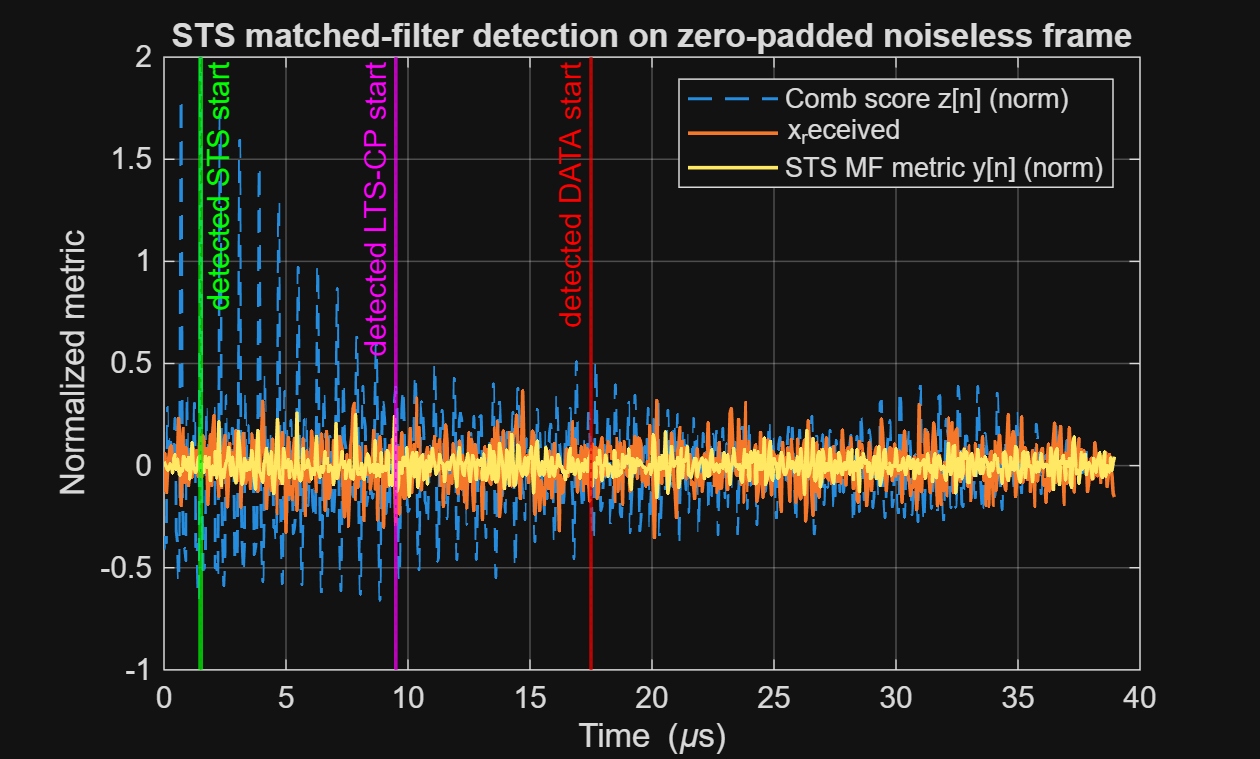



% Truth (no legend)
xline(t(true_frame_start), 'k:', 'HandleVisibility','off');
xline(t(true_lts_start),   'k:', 'HandleVisibility','off');
xline(t(true_data_start),  'k:', 'HandleVisibility','off');

% Detected (no legend entries)
xline(t(max(idx_sts,1)),    'g-', 'LineWidth',1.6, 'Label','detected STS start', ...
    'LabelHorizontalAlignment','right','HandleVisibility','off');
xline(t(max(idx_lts_cp,1)), 'm-', 'LineWidth',1.2, 'Label','detected LTS-CP start', ...
    'LabelHorizontalAlignment','left','HandleVisibility','off');
xline(t(max(idx_data,1)),   'r-', 'LineWidth',1.2, 'Label','detected DATA start', ...
    'LabelHorizontalAlignment','left','HandleVisibility','off');

xlabel('Time (\mus)'); ylabel('Normalized metric');
title('STS matched-filter detection on zero-padded noiseless frame');
legend('Location','best');

In this figure we can see that the result of STS matched filter (yellow curve) has several peaks in the STS region like a comb, and the comb filter will match those 10 peaks and find the starting index of the short training sequence, same as the case of the noiseless filter.

% Print offsets (should be 0 in noiseless test)
fprintf('Detected vs GT offsets (samples):\n');

Detected vs GT offsets (samples):


fprintf('  STF start : %d\n', idx_sts - true_frame_start);

  STF start : 0


fprintf('  LTS start : %d\n', idx_lts_cp - true_lts_start);

  LTS start : 0


fprintf('  DATA start: %d\n', idx_data - true_data_start);

  DATA start: 0


Yes it correctly identify the starting time point

## (8) LTS matched filter

Similar to the case in short training sequence filter.

let $l^*[k]$ be the conjugate time domain signal of one LTS signal, and $r[n]
$ is the received time sequence.

let $y[n] = \sum_{k=0}^{k=63}r[n-k]l^*[k]
$, (conv of r and l*)

and $z[n] = y[n]+y[n+64]
$

Find $n$ s.t. $z[n]$ has maximum value, then $n$ is the start of LTS, we can then add the corresponding time delay to obtain the start of STS and data frames.

## (9) LTS matching on noisy channel

LT_len = 64;
num_data_syms = 5;
lts_len = Ncp_LTS+2*LT_len;

zeropad_len = 30;
true_frame_start = zeropad_len+1;
true_lts_start = true_frame_start+sts_len;
true_data_start = true_lts_start+lts_len;

x_received_clean = [zeros(1, zeropad_len), frame, zeros(1, zeropad_len)];
SNRdB = 0; SNRlin = 10^(SNRdB/10);
sigPwr_frame = mean(abs(frame).^2);                   % average power of the non-zero frame
N0 = sigPwr_frame / SNRlin;                           % E{|w|^2}
w  = sqrt(N0/2) * (randn(size(x_received_clean)) + 1j*randn(size(x_received_clean)));
x_received = x_received_clean + w;                    % noisy stream

%yL = filter(conj(fliplr(lts_sym)), 1, x_received);  % correlation output
l = conj(fliplr(lts_sym));
yL_full = conv(x_received, l, 'full');
yL = yL_full(1:length(x_received));
combL = zeros(1, 2*N);
combL(1) = 1;
combL(N+1) = 1;
zL = conv(yL, combL, 'full');
zL = zL(numel(combL):end);
[~, zL_max_index] = max(zL);
idx_lts1 = zL_max_index;
idx_lts_cp = idx_lts1 - Ncp_LTS; % LTS-CP start (32 samples before LTS1)
idx_sts = idx_lts_cp - sts_len;
idx_data = idx_lts_cp + (Ncp_LTS + 2*N); 

t_us = (0:length(x_received)-1)/Fs * 1e6;
figure; hold on; grid on; box on;

xline(t_us(max(idx_lts_cp,1)), 'm-', 'LineWidth',1.2, 'Label','detected LTS-CP start', ...
    'LabelHorizontalAlignment','left', 'HandleVisibility','off');
xline(t_us(max(idx_lts1,1)),   'g-', 'LineWidth',1.2, 'Label','detected LTS1 start', ...
    'LabelHorizontalAlignment','left', 'HandleVisibility','off');
xline(t_us(max(idx_data,1)),   'r-', 'LineWidth',1.2, 'Label','detected DATA start', ...
    'LabelHorizontalAlignment','left', 'HandleVisibility','off');

plot(t_us, zL,  '--', 'LineWidth', 1.3, 'DisplayName','Two-peak score z_L[n] (norm)');

plot(t, x_received, 'LineWidth', 1.4, 'DisplayName','x_received')

plot(t_us, yL, '-.',  'LineWidth', 1.3, 'DisplayName','LTS MF metric y_L[n] (norm)');

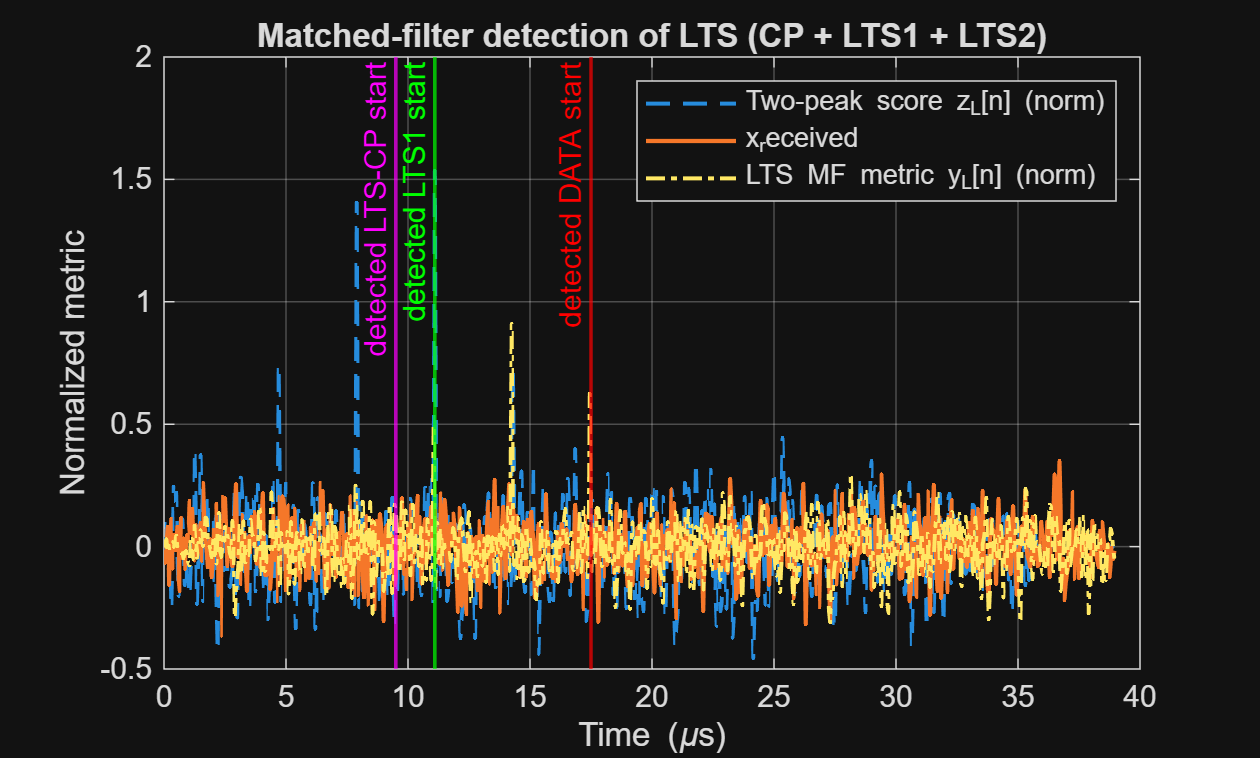



xlabel('Time (\mus)'); ylabel('Normalized metric');
title('Matched-filter detection of LTS (CP + LTS1 + LTS2)');
legend('Location','northeast');

From the figure we can identify 2 main peaks for the result of LTS matched filter curve (yellow curve), corresponding to the 2 repeat of long traning sequence. The comb filter will then identify the 2 peaks and find the starting index of the LTS after cyclic prefix.

fprintf('Detected vs GT offsets (samples):\n');

Detected vs GT offsets (samples):


fprintf('STS start : %d\n', idx_sts - true_frame_start);

STS start : 0


fprintf('LTS start : %d\n', idx_lts_cp - true_lts_start);

LTS start : 0


fprintf('DATA start: %d\n', idx_data - true_data_start);

DATA start: 0


Yes it correctly identify the frame.

## (10) STS and LTS matched filter comparison

Both STS and LTS matching can correctly identify the sequcnes in this case. However, STS filter should be mroe robust to noisy channel because it check 10 peak values.

## (11) Received signal in a multipath system

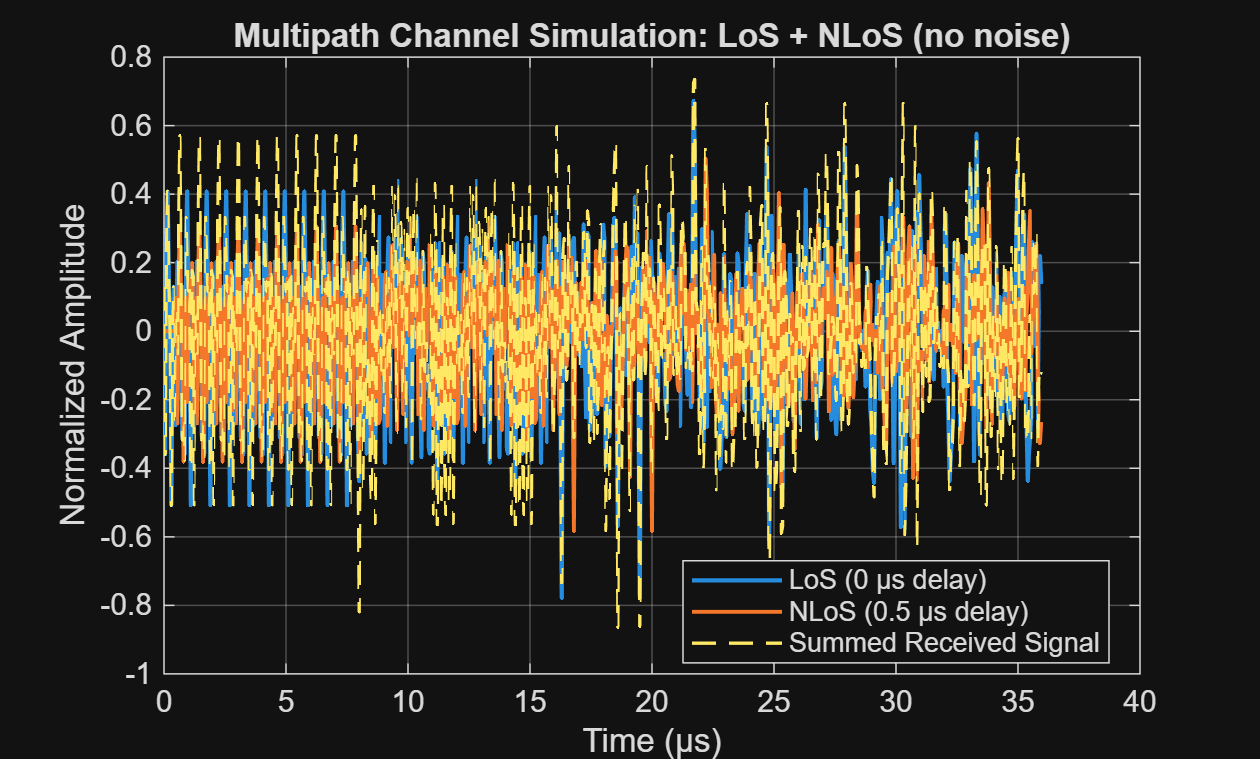

Ts = 1/Fs;
t_us = (0:length(frame)-1) * Ts * 1e6;

atten_LOS = 0.4;  
delay_LOS = 0; 
atten_NLOS = 0.3; 
delay_NLOS_us = 0.5; 
delay_NLOS_samples = round((delay_NLOS_us * 1e-6) / Ts); 

rx_LOS = atten_LOS * frame;            
rx_NLOS = atten_NLOS * [zeros(1, delay_NLOS_samples), frame(1:end-delay_NLOS_samples)];
rx_total = rx_LOS + rx_NLOS;    

% --- Plot time-domain waveforms ---
figure; hold on; grid on; box on;
plot(t_us, real(rx_LOS)/max(abs(rx_total)),  '-', 'LineWidth', 1.4, 'DisplayName', 'LoS (0 μs delay)');
plot(t_us, real(rx_NLOS)/max(abs(rx_total)), '-', 'LineWidth', 1.3, 'DisplayName', 'NLoS (0.5 μs delay)');
plot(t_us, real(rx_total)/max(abs(rx_total)),  '--', 'LineWidth', 1.1, 'DisplayName', 'Summed Received Signal');
xlabel('Time (μs)'); ylabel('Normalized Amplitude');
title('Multipath Channel Simulation: LoS + NLoS (no noise)');
legend('Location','best');

## (12) Timing imperfection

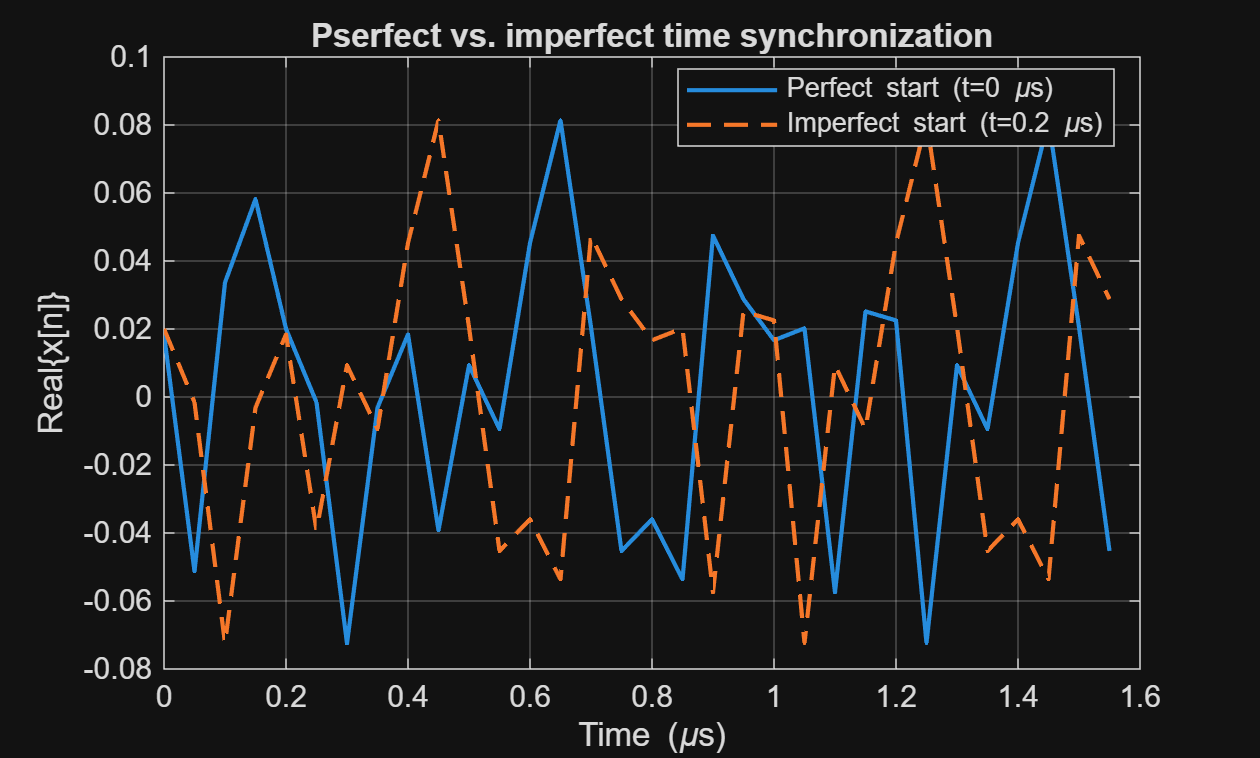

delay_us = 0.2;   
delay_samp = round(delay_us*1e-6 * Fs); 

rx_perfect = rx_total; 
rx_imperfect = rx_total(1+delay_samp:end);  

nplot = 32;
t_us = (0:nplot-1)/Fs * 1e6;

figure; hold on; grid on; box on;
plot(t_us, real(rx_perfect(1:nplot)),  '-',  'LineWidth', 1.4, 'DisplayName','Perfect start (t=0 \mus)');
plot(t_us, real(rx_imperfect(1:nplot)),'--', 'LineWidth', 1.4, 'DisplayName','Imperfect start (t=0.2 \mus)');
xlabel('Time (\mus)'); ylabel('Real\{x[n]\}');
title('Pserfect vs. imperfect time synchronization');
legend('Location','best');

We can see that the curve representing imperfect start is a left shifted version of the original samples. And if we right shift the imperfect start curve by 0.2 us, the curves will completely overlap with each other.

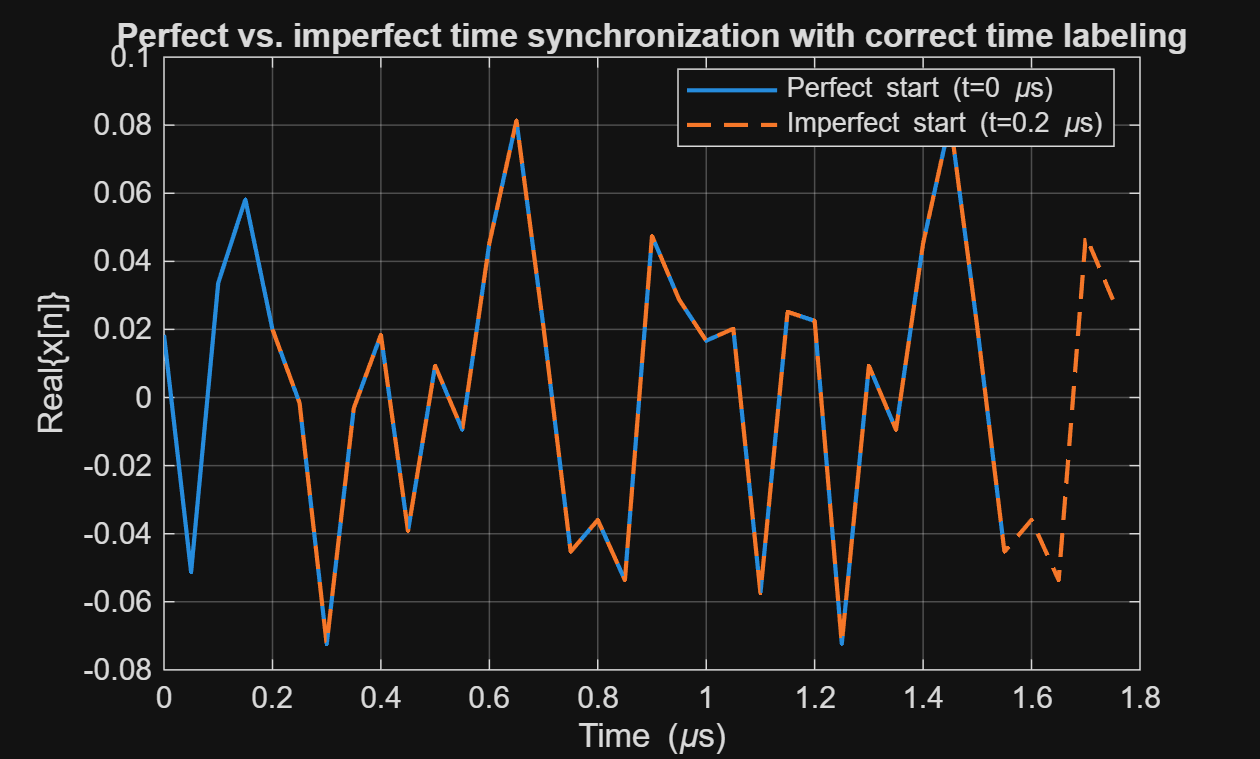

t_us_02 = t_us + 0.2;
figure; hold on; grid on; box on;
plot(t_us, real(rx_perfect(1:nplot)),  '-',  'LineWidth', 1.4, 'DisplayName','Perfect start (t=0 \mus)');
plot(t_us_02, real(rx_imperfect(1:nplot)),'--', 'LineWidth', 1.4, 'DisplayName','Imperfect start (t=0.2 \mus)');
xlabel('Time (\mus)'); ylabel('Real\{x[n]\}');
title('Perfect vs. imperfect time synchronization with correct time labeling');
legend('Location','best');

## (13) Apply LTS matched filter on imperfect time synchronization signals

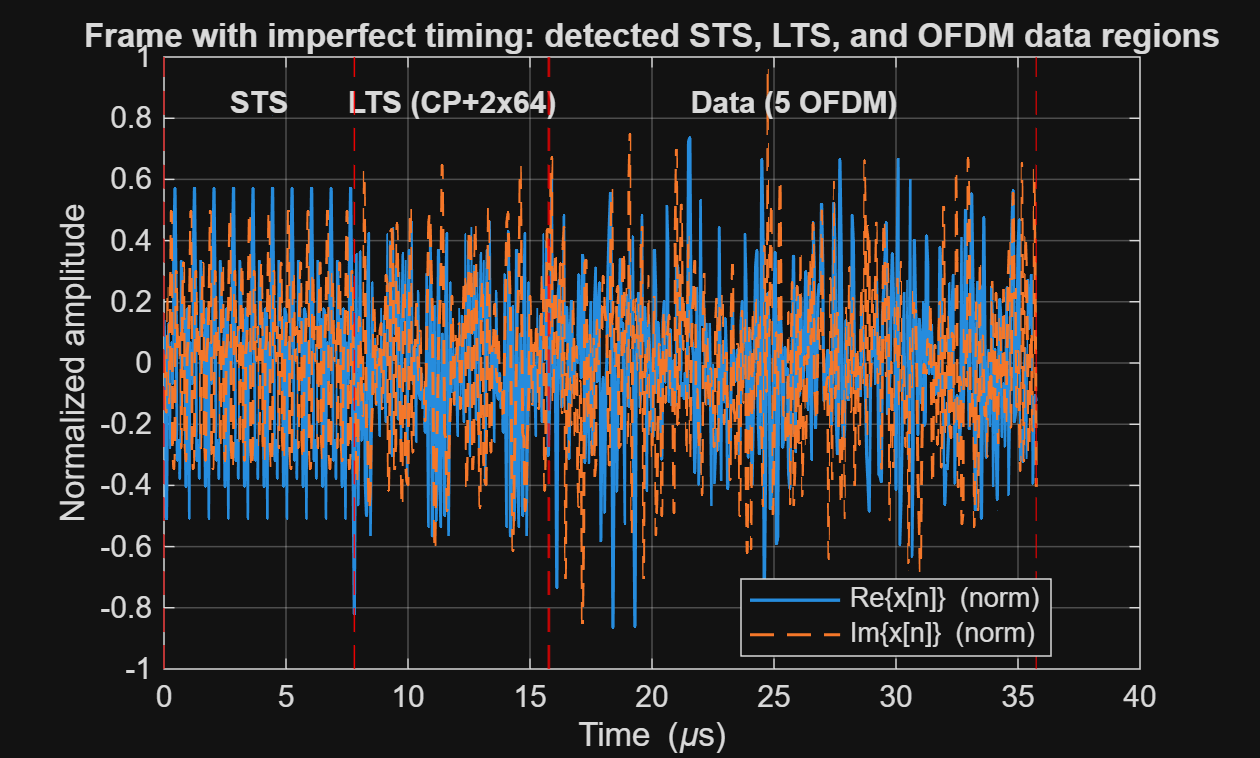

x_received = rx_imperfect(:).'; 

LT_len = 64;
lts_len = Ncp_LTS + 2*LT_len;

%yL = filter(conj(fliplr(lts_sym)), 1, x_received);
l = conj(fliplr(lts_sym));
yL_full = conv(x_received, l, 'full');
yL = yL_full(1:length(x_received));

zL = conv(yL, combL, 'full');
zL = zL(numel(combL):end);
[~, zL_max_index] = max(zL);
idx_lts1 = zL_max_index;
idx_lts_cp = idx_lts1 - Ncp_LTS; % LTS-CP start (32 samples before LTS1)
idx_sts = idx_lts_cp - sts_len;
idx_data = idx_lts_cp + lts_len; 

idx_STS_start = max(1, idx_sts);
idx_STS_end = idx_lts_cp;

idx_LTS_start = max(1, idx_lts_cp);
idx_LTS_end = idx_LTS_start + lts_len - 1;

one_data_len = N + Ncp_data;  
idx_DATA_start = max(1, idx_data);
idx_DATA_end = idx_DATA_start + num_data_syms*one_data_len - 1;

% ---- Time axis (microseconds) ----
t_us = (0:length(x_received)-1)/Fs * 1e6;

% ---- Plot time-domain frame with markers ----
figure; hold on; grid on; box on;
plot(t_us, real(x_received)/max(abs(x_received)), 'LineWidth', 1.1, 'DisplayName','Re\{x[n]\} (norm)');
plot(t_us, imag(x_received)/max(abs(x_received)), '--', 'LineWidth', 1.0, 'DisplayName','Im\{x[n]\} (norm)');

% Boundaries (hide from legend)
xline(t_us(idx_STS_start), 'r--', 'HandleVisibility','off');
xline(t_us(idx_STS_end), 'r--', 'HandleVisibility','off');
xline(t_us(idx_LTS_start), 'r--', 'HandleVisibility','off');
xline(t_us(idx_LTS_end), 'r--', 'HandleVisibility','off');
xline(t_us(idx_DATA_start), 'r--', 'HandleVisibility','off');
xline(t_us(idx_DATA_end), 'r--', 'HandleVisibility','off');

% Labels at region centers
yl = ylim;
text(t_us(round((idx_STS_start+idx_STS_end)/2)),  0.85*yl(2), 'STS',            'HorizontalAlignment','center','FontWeight','bold');
text(t_us(round((idx_LTS_start+idx_LTS_end)/2)),  0.85*yl(2), 'LTS (CP+2x64)',  'HorizontalAlignment','center','FontWeight','bold');
text(t_us(round((idx_DATA_start+idx_DATA_end)/2)),0.85*yl(2), 'Data (5 OFDM)',  'HorizontalAlignment','center','FontWeight','bold');

xlabel('Time (\mus)'); ylabel('Normalized amplitude');
title('Frame with imperfect timing: detected STS, LTS, and OFDM data regions');
legend('Location','best');

fprintf('Detected STS start     : %d\n', idx_STS_start);

Detected STS start     : 1


fprintf('Detected LTS-CP start  : %d\n', idx_LTS_start);

Detected LTS-CP start  : 157


fprintf('Detected DATA start    : %d\n', idx_DATA_start);

Detected DATA start    : 317


## (14) Channel Estimation using LTS

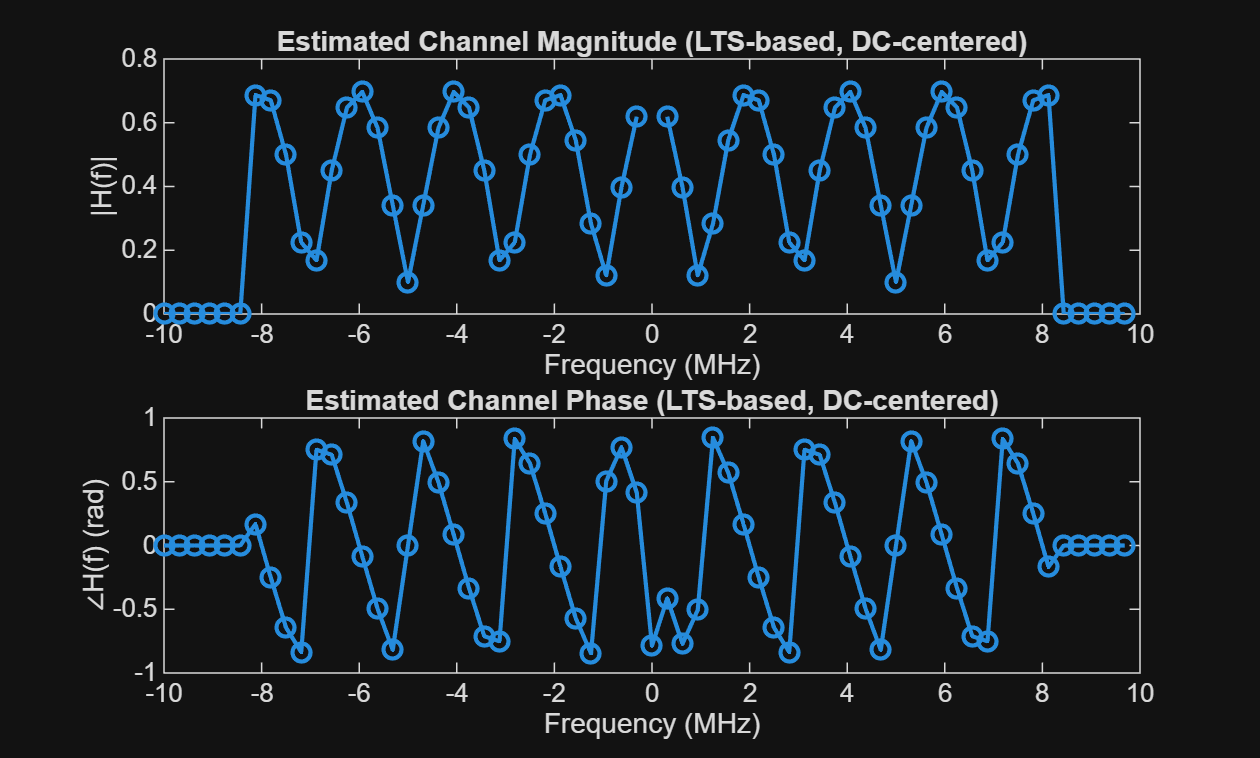

x_received = rx_imperfect(:).'; 
f_MHz  = (sc_all * dF) / 1e6; 

i_cp = idx_lts_cp;      
i_lts1 = i_cp + Ncp_LTS; 
i_lts2 = i_lts1 + N;  

y_lts1 = x_received(i_lts1 : i_lts1 + N - 1);
y_lts2 = x_received(i_lts2 : i_lts2 + N - 1);

Y1 = fftshift(fft(y_lts1, N));
Y2 = fftshift(fft(y_lts2, N));

%channel estimate using both LTSs
mask_active = ismember(sc_all, active_sc);
H1 = zeros(1,N); H2 = zeros(1,N);
H1(mask_active) = Y1(mask_active) ./ X_LTS(mask_active);
H2(mask_active) = Y2(mask_active) ./ X_LTS(mask_active);

%Average the 2 LTSs
H_est = (H1 + H2)/2;

%plot
figure; 
subplot(2,1,1); grid on; box on;
plot(f_MHz, abs(H_est), '-o', 'LineWidth', 1.4);
xlabel('Frequency (MHz)'); ylabel('|H(f)|');
title('Estimated Channel Magnitude (LTS-based, DC-centered)');

subplot(2,1,2); grid on; box on;
plot(f_MHz, unwrap(angle(H_est)), '-o', 'LineWidth', 1.4);
xlabel('Frequency (MHz)'); ylabel('∠H(f) (rad)');
title('Estimated Channel Phase (LTS-based, DC-centered)');

## (15) Observation on estimated channel

$H(f)$ changes periodically in both magnitude and phase due to the additional NLoS path.

$H(f) = \sum_{k=1}^2A_ke^{j\theta_k}e^{-j2\pi f\tau_k}$, the last term is a phase lag caused by delay. The phase of the delayed and non-delayed terms will be different, and thus when summing together, the amplitude will also be dependent on frequency.

## (16) Channel equalization using LTS

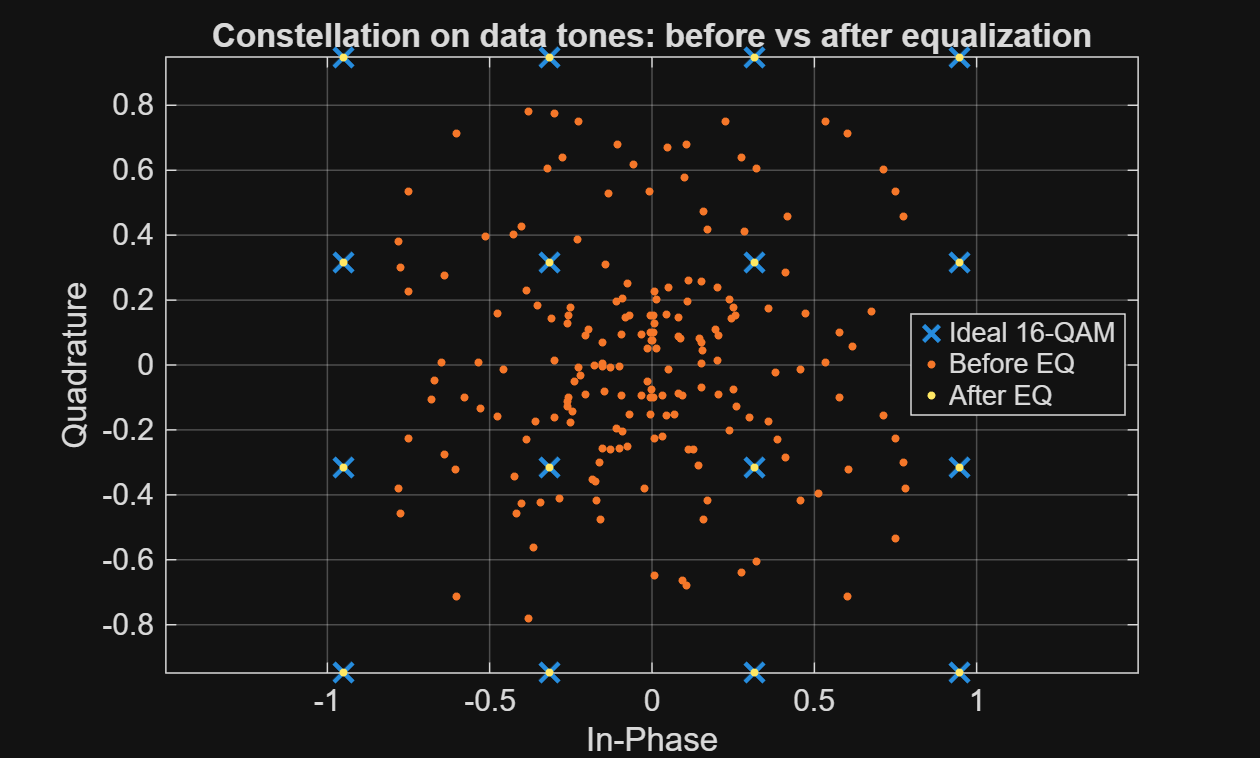

X_received_before_eq = complex(zeros(num_data_syms*n_data,1));
Y_after = complex(zeros(num_data_syms*n_data,1));
wptr = 1;

H_data = H_est(data_tones);  
% no divide by 0
H_data_safe = H_data; H_data_safe(abs(H_data_safe)<1e-12) = 1e-12;

c = [-3 -1 1 3]; [CI,CQ] = meshgrid(c,c);
CONST = (CI(:) + 1j*CQ(:))/sqrt(10);
gray_bits = [0 0; 0 1; 1 1; 1 0];
[~,iI] = ismember(CI(:),c); [~,iQ] = ismember(CQ(:),c);
label_bits = [gray_bits(iI,:) gray_bits(iQ,:)];

total_rx_data_bits = zeros(num_data_syms*bits_per_sym,1);
rptr = 1;
for k = 0:num_data_syms-1
    %1 CP-OFDM data symbol
    i0 = idx_data + k*(N + Ncp_data);
    x_cp = x_received(i0 : i0 + (N + Ncp_data) - 1);
    x_sym = x_cp(Ncp_data+1:end);  

    % FFT to frequency domain
    X_received_nocp = fftshift(fft(x_sym, N)); 
    X_received_before_eq(wptr:wptr+n_data-1) = X_received_nocp(data_tones).'; 
    X_received_equalized = X_received_nocp(data_tones) ./ H_data_safe; 
    Y_after(wptr:wptr+n_data-1) = X_received_equalized.';
    wptr = wptr + n_data;

    % for (17)
    rx_bits_mat = qamdemod( ...
        X_received_equalized, 16, 'gray', ...
        'UnitAveragePower', true, 'OutputType', 'bit'); 
    %rx_bits_mat = reshape(rx_bits_mat, 4, []).';
    rx_bits = reshape(rx_bits_mat, [], 1);

    total_rx_data_bits(rptr:rptr+bits_per_sym-1) = rx_bits;
    rptr = rptr + bits_per_sym;
end



%Plot
figure; hold on; grid on; box on;
plot(real(CONST),    imag(CONST),    'x','LineWidth',1.5,'MarkerSize',9,'DisplayName','Ideal 16-QAM');
plot(real(X_received_before_eq), imag(X_received_before_eq), '.', 'MarkerSize', 8, 'DisplayName','Before EQ');
plot(real(Y_after),  imag(Y_after),  '.', 'MarkerSize', 8, 'DisplayName','After EQ');

axis equal; xlabel('In-Phase'); ylabel('Quadrature');
title('Constellation on data tones: before vs after equalization');
legend('Location','best');

We can see that after equalization, the received symbols are correctly mapped to the original 16-QAM symbols

## (17) Demodulation after Channel equalization

BER = mean(total_rx_data_bits ~= total_tx_data_bits);
fprintf('BER over %d OFDM symbols after EQ = %.4g\n', num_data_syms, BER);

BER over 5 OFDM symbols after EQ = 0


AMAZING!!!